# Battery testing, modelling, and state estimation - SOC estimation seminar, first part

*David Vošahlík, Tomáš Haniš*

Battery State of Charge (SOC) estimation will be today's main target. It is one of the most important battery states, which is, unfortunatelly, not measurable directly. Therefore, SOC has to be estimated. There are many methods ranging from very simple ones like various lookup tables for the output voltage, through coulomb counting method up to more advanced model-based methods like Kalman Filter (KF) algorithm or its non-linear versions such as Extended Kalman Filter (EKF) or Unscented Kalman FIlter (UKF). There exists also many other KF variants but the most used variants for battery SOC estimation (KF, EKF, UKF) has been already mentioned.

## Basic SOC estimation methods

First part will cover the more basic approaches. However, a discrete time model will be needed. Therefore, first task will be to discretize a battery model with  internal resitance and open circuit voltage based voltage source. This model will be later used for the coulomb counting method. Assume sampling time 100 ms.

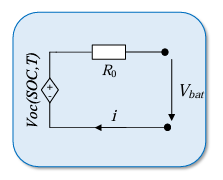


$$\begin{array}{l}
\dot{\textrm{SOC}} =-\frac{1}{C}i\\
V_{\textrm{bat}} =V_{\textrm{OC}} -{i\;R}_0 \;
\end{array}$$


Use the measured data to validate correctness of the battery model implementation.

set(groot, 'defaultTextInterpreter', 'latex')

% The model input is current i, assume only the 25 deg C temperature (3rd row in the parameters)
Battery = InitializeBatPars();              % Setup the constants
% Load the measured data

[Time, I_true, U_true, SOC_true] = load_data();

fig_Ubat = figure;
clf;
hold on
plot(Time, U_true, LineWidth=2, DisplayName='Reference U_{bat}');
fig_SOC = figure;
clf;
hold on
plot(Time, SOC_true, LineWidth=2, DisplayName='Reference SoC');

fig_drift = figure;
fig_drift_time = figure;

Ts = 0.1; % Assume sampling time 100 ms
% My guess of SOC initial condition
for SOC_init = [80 90 95 100]
% Voltage data are very noisy
SOC_sim = zeros(size(SOC_true)) + SOC_init;
U_sim = zeros(size(U_true));

for k = 1:length(Time)-1
    [SOC_sim(k+1), U_sim(k)] = BatteryModel(Time(k), SOC_sim(k), I_true(k), Ts, Battery);
end
[~, U_sim(end)] = BatteryModel(Time(end), SOC_sim(end), I_true(end), Ts, Battery);

SOC_RMSE = rms(SOC_true - SOC_sim);
Ubat_RMSE = rms(U_true - U_sim);

figure(fig_Ubat);
plot(Time, U_sim, LineWidth=2, DisplayName=sprintf('SoC_0 = %3d %%, RMSE U_{bat} = %5.1f mV', SOC_init, Ubat_RMSE * 1e3));
grid on;
xlabel('Time [s]')
ylabel('Voltage [V]');
legend(Location='best')
ylim([2.5 3.7])

figure(fig_SOC);
plot(Time, SOC_sim, LineWidth=2, DisplayName=sprintf('SoC_0 = %3d %%, RMSE SoC = %5.2f %%', SOC_init, SOC_RMSE));
grid on;
xlabel('Time [s]')
ylabel('SoC [\%]');
legend(location='best')

if SOC_init == 95
    figure(fig_drift_time);
    plot(Time, SOC_true - SOC_sim, LineWidth=2);
    xlabel('Time [s]');
    ylabel('SoC [\%]')
    legend('Deviation of simulation from reference');
    grid on

    figure(fig_drift);
    x = SOC_true(1) - SOC_true;
    y = SOC_true - SOC_sim;
    polynomial_fit = polyfit(x, y, 1)
    y_hat = polyval(polynomial_fit, x);
    rmse_fit = rms(y - y_hat)
    plot(x, [y; y_hat], LineWidth=2);
    
    xlabel('Discharged capacity [\%]');
    ylabel('SoC [\%]')
    legend('Deviation of simulation from reference', 'Linear fit');
    grid on
end

end

polynomial_fit =    -0.0502    0.0432


rmse_fit = 0.0161

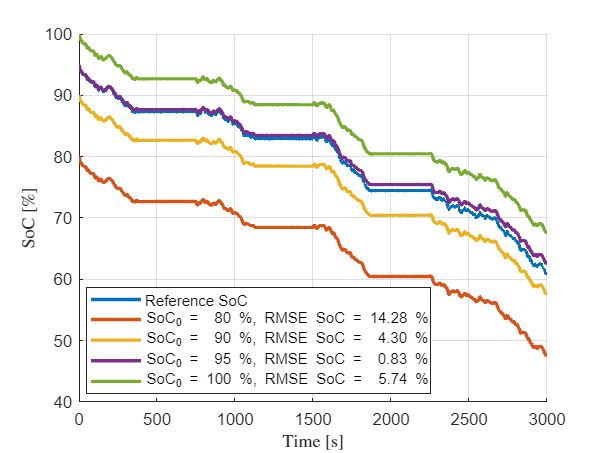


figure(fig_Ubat)
U_OC_true = interp1(Battery.SOC, Battery.Voc(3, :), SOC_true);
plot(Time, U_OC_true, LineWidth=2, DisplayName='Reference U_{OC}');

exportgraphics(fig_SOC, "figures/validation-SOC.eps");

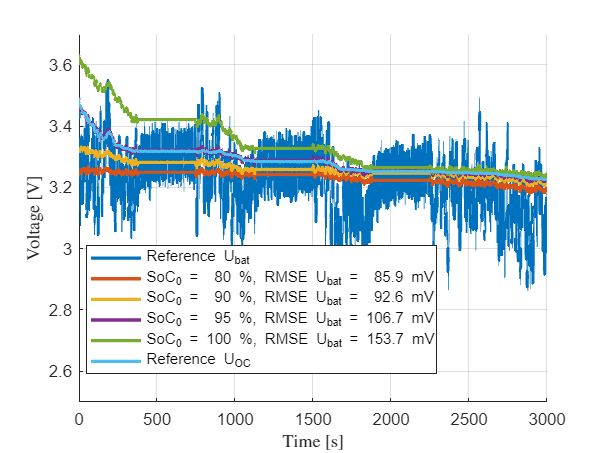

exportgraphics(fig_Ubat, "figures/validation-Ubat.eps");

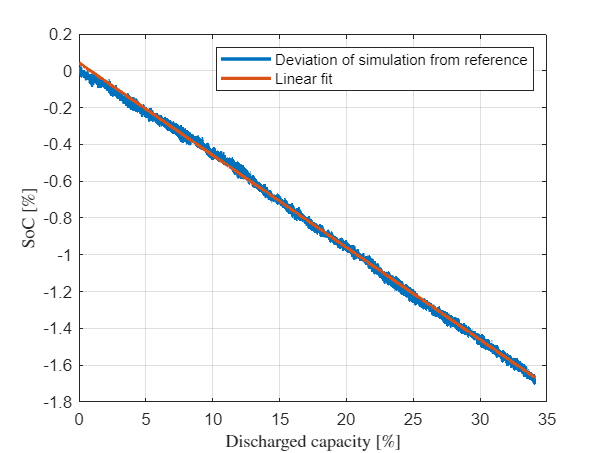

exportgraphics(fig_drift, "figures/validation-deviation.eps");

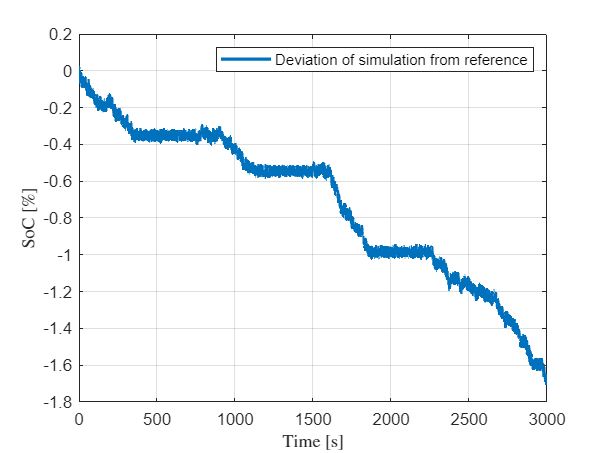

exportgraphics(fig_drift_time, "figures/validation-deviation-in-time.eps");

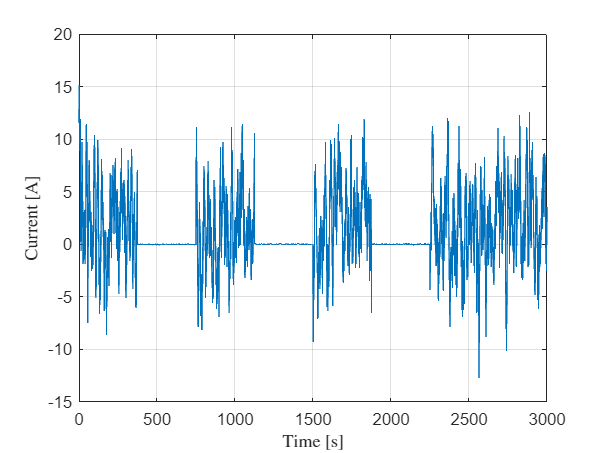

% Slowly drifts away from the true value but otherwise ok when you hit the
% correct initial conditions. If not then (almost) constant offset.

fig_I = figure;
plot(Time, I_true);
grid on;
xlabel('Time [s]')
ylabel('Current [A]');
exportgraphics(fig_I, "figures/validation-I.eps");

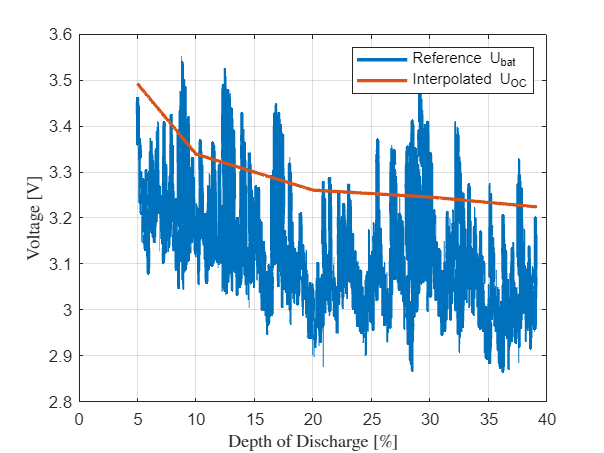


fig_incorrect_SOC = figure;
plot(100 - SOC_true, [U_true; interp1(Battery.SOC, Battery.Voc(3, :), SOC_true)], LineWidth=2);
xlabel('Depth of Discharge [\%]');
ylabel('Voltage [V]');
legend('Reference U_{bat}', 'Interpolated U_{OC}')
grid on;

exportgraphics(fig_incorrect_SOC, "figures/validation-incorrect-SOC.eps");

#### Open circuit voltage

Specifically, at first you will have to implement one of the most simple (and also inaccurate) approaches. Measure the battery terminal voltage, implement averaging over selected time period (select time period, so that the SOC RMSE is minimized). The filtered battery terminal voltage can be then used to determine battery SOC when compared to the open circuit voltage.

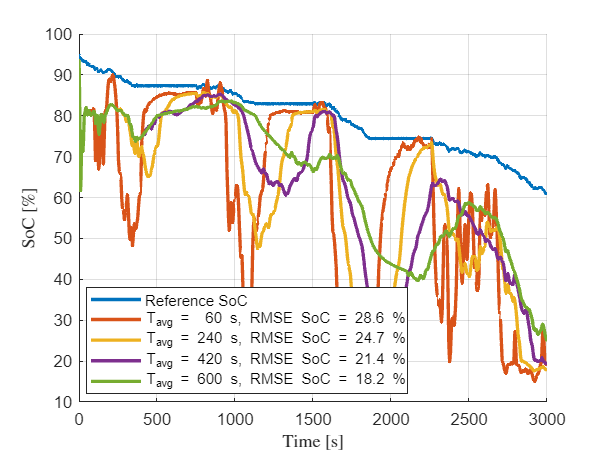

% Implement open circuit voltage SOC estimation method
% Calculate SOC using available SOC map
fig_SOC = figure;
clf
hold on
plot(Time, SOC_true, LineWidth=2, DisplayName="Reference SoC");
fig_Ubat = figure;
clf
hold on
plot(Time, U_true, LineWidth=2, DisplayName="Reference U_{bat}");
plot(Time, interp1(Battery.SOC, Battery.Voc(3, :), SOC_true), LineWidth=2, DisplayName='Interpolated U_{OC}');

SOC_ocv_best = [];

for averaging_period = 60:180:600 % in seconds
Voc = movmean(U_true, [averaging_period / Ts, 0]);
figure(fig_Ubat);
plot(Time, Voc, Linewidth=2, DisplayName=sprintf('T_{avg} = %3d s', averaging_period));
xlabel('Time [s]');
legend(location='best');
ylabel('Voltage [V]')
grid on;

SOC_ocv = interp1(Battery.Voc(3, :), Battery.SOC, Voc);

% Select the best hyperparameter
if averaging_period == 240
SOC_ocv_best = SOC_ocv;
end

SOC_ocv_error = rms(SOC_ocv - SOC_true);

figure(fig_SOC)
plot(Time, SOC_ocv, LineWidth=2, DisplayName=sprintf('T_{avg} = %3d s, RMSE SoC = %4.1f %%', averaging_period, SOC_ocv_error));
xlabel('Time [s]');
ylabel('SoC [\%]');
grid on;
legend(location='best');
end
exportgraphics(fig_SOC, "figures/OCV-SOC.eps");

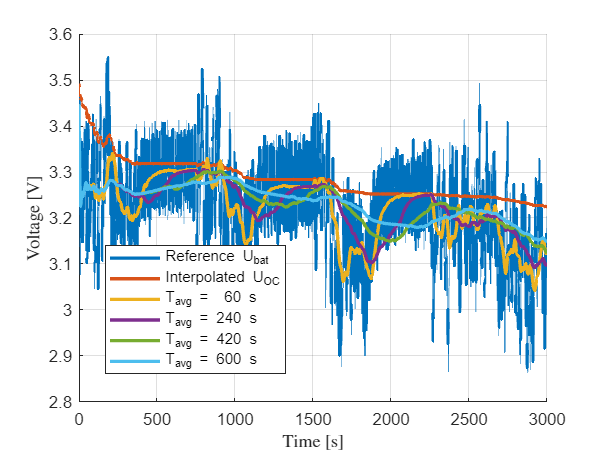

exportgraphics(fig_Ubat, "figures/OCV-Ubat.eps");

#### Couloumb counting

Next task will be to implement coulomb counting method to estimate the battery SOC. Coulomb counting, as the name suggests counts the coulombs flowing from or to the battery. This method is more advanced and accurate then the previous one. However, requires more precise guess of the initial battery SOC. Your task is to implement the Coulomb counting method.

% Implement Coulomb counting
% Capacity from Ah to C and then SOC from [0, 1] to %
SOC_cc = 80 - Ts * cumsum(I_true) / (Battery.C * 3600) * 100; 

SOC_cc_error = rms(SOC_cc - SOC_true)

SOC_cc_error = 14.2850

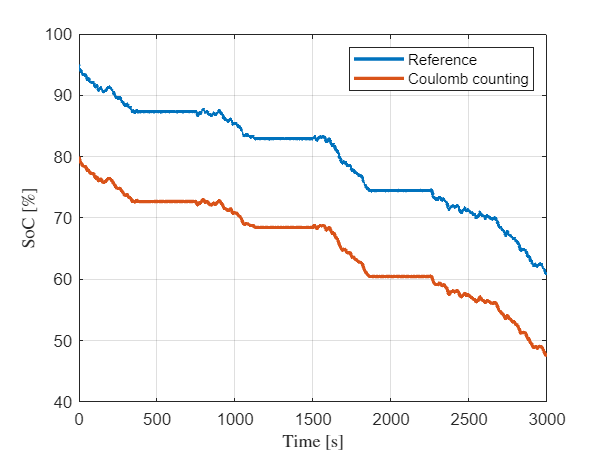

fig_SOC = figure;
plot(Time, [SOC_true; SOC_cc], LineWidth=2);
xlabel('Time [s]');
ylabel('SoC [\%]');
grid on;
legend('Reference', 'Coulomb counting')

% No graphics exported as there is already a better coulomb counting plot above

#### Homework - Combination of both approaches 

As your homework, you will have to combine both methods and compare RMSE of all three methods. The true data are stored in the vector SOC_true which contains state values of simulated 2RC battery model. 

The combination of both methods might be beneficial. The main idea is following. If no current is drawn from the battery it evenntually goes to a steady state. The SOC of the steady state can be determined using OCV curve. Using this value, the coulomb counting method might be initialized (or reseted).

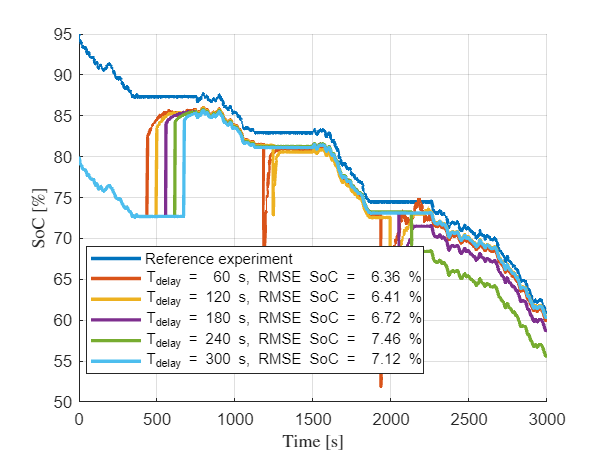

%Combine both methods

fig_SOC = figure;
clf
hold on;
plot(Time, SOC_true, LineWidth=2, DisplayName='Reference experiment');

SOC_combined_best = [];

% Implement Coulomb counting with conditional reset
for delay_time = [60 120 180 240 300]
SOC_combined = zeros(size(SOC_true)) + 80;
for k = 1:length(Time)-1
    % Coulomb counting part
    SOC_combined(k+1) = SOC_combined(k) - Ts * I_true(k) / (Battery.C * 3600) * 100;
    % Check last n values
    current_start = round(max(1, k - delay_time / Ts));
    mask = current_start:k;
    I = I_true(mask);
    [lower, upper] = bounds(I);
    % If the battery is idle, reset
    if upper - lower < 1e-1 && k * Ts > delay_time
        % Reset using the OCV method
        OCV = mean(U_true(mask));
        SOC_combined(k+1) = interp1(Battery.Voc(3, :), Battery.SOC, OCV);
    end
end
SOC_combined_error = rms(SOC_combined - SOC_true);
plot(Time, SOC_combined, LineWidth=2, DisplayName=sprintf('T_{delay} = %3d s, RMSE SoC = %5.2f %%', delay_time, SOC_combined_error));

% Select the best hyperparameter
if delay_time == 300
    SOC_combined_best = SOC_combined;
end
end

xlabel('Time [s]');
ylabel('SoC [\%]');
ylim([50 95])
grid on;
legend(location='best')
exportgraphics(fig_SOC, "figures/combination-SOC.eps");
a1 = gca;
fig_SOC_detail = figure;
a2 = copyobj(a1, fig_SOC_detail);

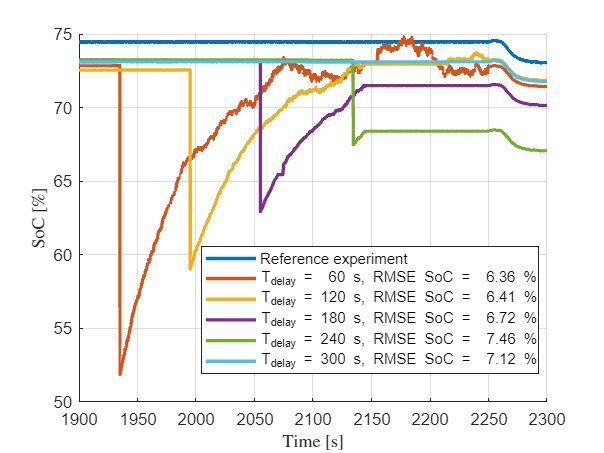

xlim([1900 2300])
ylim([50 75])
legend(location='best')
exportgraphics(fig_SOC_detail, "figures/combination-SOC-detail.eps");

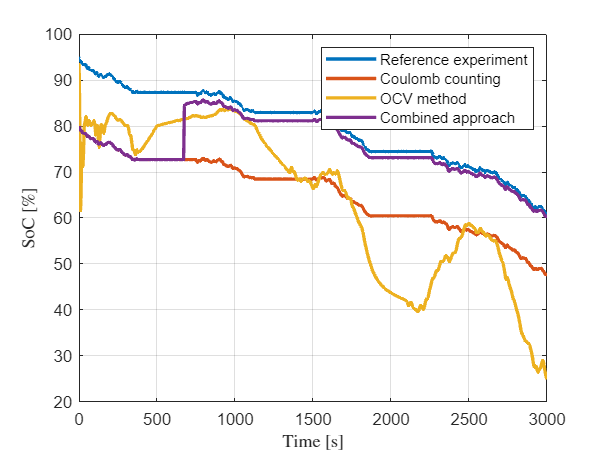


fig_comparison = figure;
plot(Time, [SOC_true; SOC_cc; SOC_ocv; SOC_combined_best], LineWidth=2);
xlabel('Time [s]');
ylabel('SoC [\%]');
grid on;
legend('Reference experiment', 'Coulomb counting', 'OCV method', 'Combined approach')
exportgraphics(fig_comparison, "figures/comparison-SOC.eps");

function Bat = InitializeBatPars()

% Battery parameters - 
% columns represent SOC <10%, 100%>, 
Bat.SOC = 10:10:100;
Bat.Temp = 35:-5:-10;
% rows the temperature <35, -10> degC
Bat.R1 = [
    0.0305    0.0323    0.0290    0.0311    0.0316    0.0299    0.0287    0.0293    0.0304    0.0288
    0.0410    0.0403    0.0396    0.0395    0.0411    0.0360    0.0436    0.0416    0.0394    0.0405
    0.0470    0.0487    0.0501    0.0512    0.0479    0.0480    0.0478    0.0516    0.0497    0.0512
    0.0580    0.0570    0.0599    0.0612    0.0608    0.0612    0.0604    0.0602    0.0612    0.0602
    0.0691    0.0703    0.0712    0.0656    0.0685    0.0699    0.0670    0.0711    0.0721    0.0735
    0.0802    0.0816    0.0802    0.0773    0.0830    0.0778    0.0786    0.0808    0.0796    0.0788
    0.0923    0.0894    0.0936    0.0871    0.0899    0.0887    0.0888    0.0880    0.0907    0.0885
    0.0994    0.0989    0.1006    0.1008    0.1033    0.1005    0.1008    0.1015    0.0995    0.0965
    0.1125    0.1094    0.1136    0.1129    0.1091    0.1080    0.1119    0.1087    0.1105    0.1118
    0.1210    0.1178    0.1186    0.1193    0.1212    0.1219    0.1206    0.1188    0.1209    0.1217];
Bat.R2 = [
    0.1098    0.1077    0.1074    0.1105    0.1118    0.1091    0.1092    0.1121    0.1108    0.1086
    0.1218    0.1178    0.1153    0.1201    0.1194    0.1192    0.1191    0.1229    0.1188    0.1187
    0.1304    0.1291    0.1318    0.1288    0.1321    0.1320    0.1340    0.1301    0.1303    0.1317
    0.1406    0.1397    0.1363    0.1376    0.1393    0.1394    0.1419    0.1435    0.1367    0.1402
    0.1502    0.1496    0.1501    0.1506    0.1520    0.1523    0.1491    0.1503    0.1485    0.1508
    0.1609    0.1611    0.1601    0.1573    0.1613    0.1589    0.1613    0.1575    0.1584    0.1618
    0.1702    0.1708    0.1745    0.1679    0.1696    0.1719    0.1693    0.1656    0.1710    0.1704
    0.1856    0.1815    0.1799    0.1827    0.1783    0.1790    0.1814    0.1793    0.1800    0.1811
    0.1877    0.1936    0.1890    0.1892    0.1879    0.1904    0.1928    0.1914    0.1877    0.1914
    0.1963    0.2024    0.2005    0.1997    0.1995    0.2019    0.1968    0.2006    0.2000    0.2023];
Bat.C1 = [
    160.9517  162.0682  161.8479  160.1290  158.0189  157.0346  164.0487  161.2948  158.4844  160.1560
  172.8245  170.5831  170.5338  171.2006  167.6539  169.9124  165.2810  169.1487  168.8721  172.6488
  180.0452  178.4446  181.2833  177.2770  176.5491  181.9217  178.9801  182.0972  181.1103  179.5737
  189.9043  191.1334  190.8510  190.6952  190.5765  193.4765  187.3567  191.3214  188.8864  189.7310
  203.4027  197.2348  197.3706  199.6363  196.8116  199.1396  198.7277  205.0175  198.2098  197.6573
  208.9806  210.4889  209.1672  208.1209  210.2204  206.7454  210.6357  212.1269  209.1813  207.2295
  219.9943  221.6169  222.4494  219.9249  221.5741  220.3327  220.2761  222.3138  219.6782  220.6210
  231.8397  230.4261  229.9128  226.2074  229.9955  230.7525  228.5785  230.1060  230.8187  229.5010
  240.2996  241.7594  241.1648  235.7440  240.1862  239.5461  241.5540  237.4232  238.0947  241.0075
  252.8099  254.0778  247.9870  247.6462  249.2437  247.7022  251.2448  249.2576  250.6346  248.2147];
Bat.C2 = 1000*[   
    1.7382    1.6717    1.7083    1.6965    1.6886    1.7292    1.7084    1.6761    1.7211    1.6715
    1.7524    1.7512    1.7570    1.7258    1.7450    1.7910    1.7580    1.7629    1.7350    1.7643
    1.8209    1.7918    1.8070    1.7941    1.7686    1.8024    1.8019    1.7929    1.7813    1.7844
    1.8455    1.8426    1.8354    1.7854    1.8405    1.8302    1.8599    1.8509    1.8246    1.8563
    1.8967    1.8728    1.9065    1.8783    1.8732    1.9240    1.9216    1.8841    1.9100    1.9281
    1.9638    1.9656    1.9397    1.9215    1.9506    1.9381    1.9694    1.9190    2.0058    1.9580
    2.0111    2.0088    1.9821    1.9797    2.0171    1.9906    1.9886    2.0034    2.0146    2.0186
    2.0276    2.0482    2.0259    2.0457    2.0581    2.0677    2.0662    2.0488    2.0345    2.0179
    2.0693    2.1204    2.1208    2.0935    2.0860    2.0723    2.1035    2.1240    2.1167    2.1132
    2.1280    2.1325    2.1331    2.1889    2.1174    2.1109    2.1399    2.1660    2.1274    2.1928];
% capacity [Ah]
Bat.C = 3;
% internal resistance [Ohm]
Bat.R0 = [
    0.0011087    0.0011036     0.001136    0.0010848    0.0011335     0.001095     0.001094    0.0010897    0.0010689    0.0010915
    0.0011899    0.0012253    0.0011977    0.0011861    0.0012025    0.0011962     0.001186    0.0012159    0.0012383    0.0011789
     0.001302     0.001295    0.0012936    0.0013256    0.0013106    0.0012793    0.0013167    0.0012866    0.0013122     0.001313
    0.0014239    0.0013959    0.0014164    0.0013838     0.001381    0.0013935    0.0013861    0.0014237     0.001387    0.0013936
    0.0015024     0.001456    0.0015098    0.0014753    0.0015171    0.0015153    0.0014908    0.0015158    0.0015523    0.0015354
    0.0015793    0.0015845    0.0016153    0.0016043    0.0016078    0.0016349    0.0016177    0.0016058     0.001611    0.0016302
    0.0016829    0.0016721    0.0017156    0.0017402    0.0016769    0.0016768    0.0017087    0.0017001    0.0017059    0.0017033
    0.0017966    0.0017923    0.0017704    0.0018005    0.0018008    0.0018475    0.0018179    0.0018073    0.0017844    0.0017943
    0.0018962    0.0019105    0.0019108    0.0019062     0.001891    0.0019305    0.0019101    0.0019705    0.0018787     0.001923
    0.0019827    0.0020305    0.0019982    0.0019812    0.0020022    0.0020034     0.001992    0.0019978    0.0019646    0.0019771];
Bat.Voc = [
    2.9827       3.1813       3.2034       3.2184       3.2411       3.2606       3.2835       3.2974       3.3803       3.6798
        2.958       3.1571       3.1826       3.2028       3.2171       3.2432       3.2604       3.2795       3.3594       3.6591
       2.9436       3.1388       3.1588         3.18       3.1981       3.2221       3.2455       3.2605        3.339       3.6444
       2.9193       3.1163       3.1404       3.1614       3.1804       3.2004       3.2194        3.243       3.3214       3.6216
       2.8971       3.0991       3.1216       3.1383       3.1593       3.1818       3.2011       3.2229       3.3027       3.6014
       2.8788       3.0819       3.1008       3.1178       3.1426       3.1604       3.1832       3.1999       3.2843        3.578
       2.8619       3.0614       3.0814       3.0998       3.1227       3.1392       3.1655       3.1818       3.2601       3.5609
       2.8421       3.0446       3.0598       3.0795       3.0988       3.1207       3.1406       3.1594       3.2403        3.541
       2.8203       3.0203       3.0399       3.0624       3.0818       3.1001       3.1184       3.1413       3.2187       3.5178
       2.8006       2.9957       3.0202       3.0412       3.0628       3.0793       3.1016       3.1238       3.2032       3.4995];
end

function [x_next, y] = BatteryModel(t, x, u, deltaT, Battery)
    % Inputs u = [I]
    % Outputs y = [Ubat]
    % States x = [SOC]

    SOC = x(1);
    I = u(1);

    % Assume 25 degC (3rd row of parameters)
    R0 = interp1(Battery.SOC, Battery.R0(3, :), SOC);
    Voc = interp1(Battery.SOC, Battery.Voc(3, :), SOC);

    % State evolution
    SOC_next = SOC - deltaT * I / (Battery.C * 3600) * 100;
    % Output equation
    Ubat = Voc - I * R0;
    
    x_next = [SOC_next];
    y = [Ubat];
end

function dxdt = myode(t,x,ut,u, fun)
% function wrapper for the ode45 solver so that it is able to solve the differential equations
uInterp = zeros(size(u, 1), 1);
for i = 1:size(u, 1)
    uInterp(i) = interp1(ut,u(i,:),t); % Interpolate the data set (ut,u) at time t
end
dxdt = fun(x, uInterp); % Evaluate ODE at time t
end

function [Time, Current, Voltage, SOC] = load_data()
    data = load('SOC_Estimation1_Data.mat');

    Time = data.timeMeas;
    Current = data.CurrentMeas;
    Voltage = data.trmVoltMeas;
    SOC = data.x_bat;
end